# Range-Velocity Matrix

clear; close all;

## 1. Построение сигнала

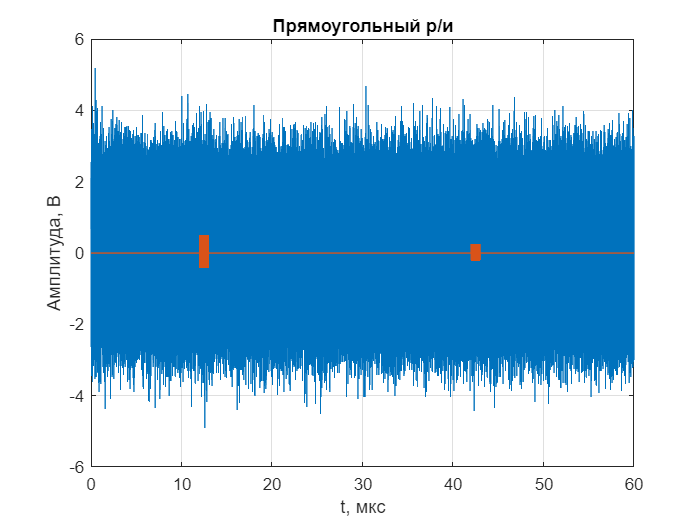

% Параметры модели
type_signal = "Прямоугольный р/и";
noise       = 0;
f0     = 3e9;           % несущая частота, Гц
fs     = 5 * f0;        % частота дискретизации, Гц
dt     = 1 / fs;        % период дискретизации, с
T      = 60e-6;         % время наблюдения (длительность строба), с
ti     = 1e-6;          % длительность импульса, с
N      = 511;
tdiskr = ti/N;
n_diskr = fix(tdiskr/dt);
mpoly  = 0x211;
minit  = 0x32;
deltaF = 10e6;          % девиация частоты, Гц (ЛЧМ)
A      = 1;             % амплитуда сигнала, В
t      = 0:dt:T-dt;     % вектор отсчетов времени строба, с
t_s    = 0:dt:ti-dt;    % вектор отсчетов времени импульса, с

% Параметры принимаемых сигналов
f_r = [f0, f0]';        % частоты принимаемых сигналов, Гц
A_r = [A, A/2]';        % Амплитуды принимаемых сигналов, В
t_z = T*[0.2, 0.7]';    % Времена задержки принимаемых сигналов относительно начала строба, с

% Выбор типа сигнала
switch type_signal
    case "Прямоугольный р/и"
        s_op = A/2 * complex(cos(2*pi*f0*t_s), sin(2*pi*f0*t_s));
        s_r  = A_r/2 .* complex(cos(2*pi*f_r*t_s), sin(2*pi*f_r*t_s));
    case "ЛЧМ"
        s_op = A/2 *complex(cos(2*pi*(f0+deltaF/ti*t_s).*t_s), ...
                            sin(2*pi*(f0+deltaF/ti*t_s).*t_s));
        s_r  = A_r/2 .* complex(cos(2*pi*(repmat(f_r,1,length(t_s))+deltaF/ti*t_s).*t_s), ...
                                sin(2*pi*(repmat(f_r,1,length(t_s))+deltaF/ti*t_s).*t_s));
    case "ФКМ"
        k = repelem(Generate_MLS(mpoly, minit),1,n_diskr);
        t_s(length(k)+1:end) = [];
        s_op = A/2 * complex(cos(2*pi*f0*t_s + k*pi), ...
                             sin(2*pi*f0*t_s + k*pi));
        s_r  = A_r/2 .* complex(cos(2*pi*f_r*t_s + repmat(k,length(f_r),1)*pi), ...
                                sin(2*pi*f_r*t_s + repmat(k,length(f_r),1)*pi));
    otherwise
        error("Unknown signal type: %s", type_signal);
end

% Формирование суммы принимаемых сигналов
s = zeros(1,length(t));
for i = 1:length(t_z)
   s = s + [zeros(1,fix(t_z(i)/dt)), s_r(i,:), zeros(1,length(t)-fix(t_z(i)/dt)-length(t_s))]; 
end

% Добавление шума
s_n = db2mag(noise)*complex(randn(1,length(t)), randn(1,length(t))) + s;

plot(t*1e6,real(s_n),t*1e6,real(s));
grid on; title(type_signal);
xlabel("t, мкс"); ylabel("Амплитуда, В");

## 2. Корреляционная обработка

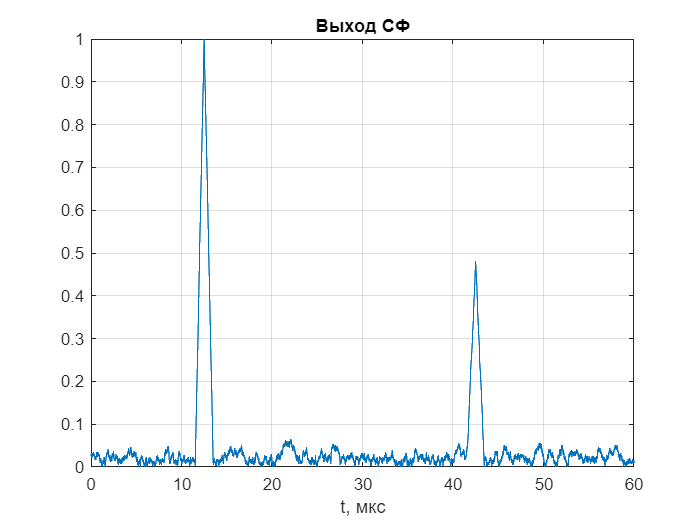

R = conv(s_n, conj(flip(s_op)), 'same');
R = R/max(R);
maxIndices = islocalmax(abs(R),"MinProminence",0.1);
plot(t*1e6,abs(R)); grid on;
xlabel("t, мкс"); title("Выход СФ");

for i = t(maxIndices)
   fprintf("Время прихода сигнала:\t%.2f мкс\n", (i-ti/2)*1e6); 
end

Время прихода сигнала:	12.00 мкс
Время прихода сигнала:	42.00 мкс
